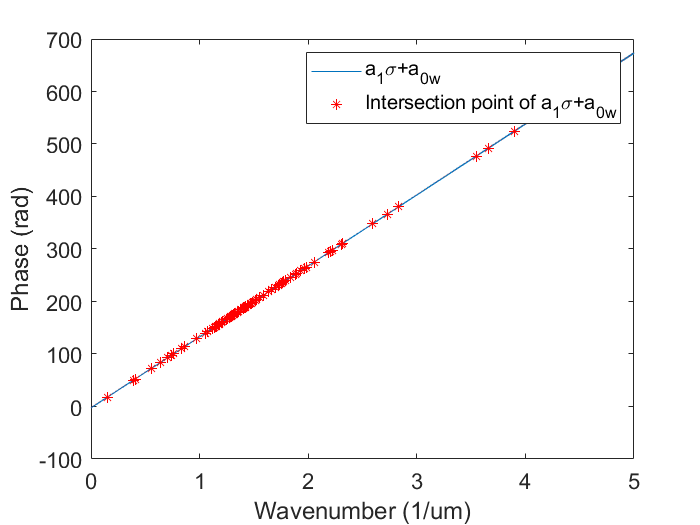

clear all; clc;
%-----------------------------------------------------------------------------------------------------
% 生成白光干涉信号
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
% plot(spectrum_frequency,spectrum_intensity)
%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
% plot(spectrum_frequency,spectrum_intensity,'LineWidth',2);
% xlabel('Wavenumber (1/um)') 
% ylabel('Intentity (a.u.)')
% ax = gca;
% ax.FontSize = 13;
%生成白光干涉信号
z0 = 30;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency));
end

%disp("生成的白光干涉信号");
% plot(z,interference_signal);
%-----------------------------------------------------------------------------------------------------
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
%fft补零
Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
% abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.2));
[~, indix_max] = min(abs(sigma-2.0));
% ang_fis = unwrap(ang_fis(indix_min:indix_max));
%plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max));
% plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));
p1 = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1);
%计算z0,误差
a01 = wrapToPi(p1(2));
p1(1) = p1(1)-4*pi*z(1);
calculate_z0 = p1(1)/(-4*pi);
diff_z0 = abs(calculate_z0-z0);

%-----------------------------------------------------------------------------------------------------
%加入色散
%色散公式
lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
% plot(spectrum_frequency,index,'LineWidth',2);
% xlabel('Wavenumber (1/um)') 
% ylabel('Refractive index')
% ax = gca;
% ax.FontSize = 13;

%色散
lEpsilon = 20; %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));

Number = 15;
xa1 = zeros(1,Number);
xa0 = zeros(1,Number);
za2 = zeros(1,Number);
zp2 = zeros(1,Number);
for num = 1:Number
noise = gnoise(0,0.01,N);
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0+noise(i)).*spectrum_frequency+...
        4*pi*(index-1).*spectrum_frequency*lEpsilon));
end
% plot(z,noise,'LineWidth',2);
% xlim([17 22])
% xlabel('z (um)') 
% ylabel('{ε_n(z)} (um)')
% ax = gca;
% ax.FontSize = 13;
% std(noise,0,2)
%disp("生成有色散的白光干涉信号");
% plot(z,interference_signal);
%-----------------------------------------------------------------------------------------------------
%傅里叶变换
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
% plot(z,interference_signal,'LineWidth',2);
% xlabel('z (um)') 
% ylabel('Intentity (a.u.)')
% xlim([16,23])
% ax = gca;
% ax.FontSize = 13;
%fft补零
Nftt = 2^15;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.1));
[~, indix_max] = min(abs(sigma-2.1));
% plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),'LineWidth',2);
% xlabel('Wavenumber (1/um)') 
% ylabel('Phase (rad)')
% ax = gca;
% ax.FontSize = 13;

% ang_fis1 = ang_fis+4*pi*z0*sigma;
% plot(sigma(indix_min:indix_max),ang_fis1(indix_min:indix_max),'LineWidth',2);
% xlabel('Wavenumber (1/um)') 
% ylabel('Phase (rad)')
% ax = gca;
% ax.FontSize = 13;
% p1 = polyfit(sigma(indix_min:indix_max),ang_fis1(indix_min:indix_max),1)
% ang_fis_fit2 = p1(1)*sigma(indix_min:indix_max)+p1(2);
% hold on 
% plot(sigma(indix_min:indix_max),ang_fis_fit2,'LineWidth',2);
% hold off
% legend('measured phase distribution','least squares line','Location','northwest')
% 


% plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max),'LineWidth',2);
% xlabel('Wavenumber (1/um)') 
% ylabel('Intentity (a.u.)')
% ax = gca;
% ax.FontSize = 13;
% plot(sigma,abs_fis);

[~, indix_min1] = min(abs(sigma-1.2));
[~, indix_max1] = min(abs(sigma-2.0));
p = polyfit(sigma(indix_min1:indix_max1),ang_fis(indix_min1:indix_max1),1);
% p = robustfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),'andrews');
p = flip(p);
ang_fis_fit = p(2)*sigma(indix_min:indix_max)+p(1);
% plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max)-ang_fis_fit,'LineWidth',2);
% xlabel('Wavenumber (1/um)') 
% ylabel('Phase (rad)')
% ax = gca;
% ax.FontSize = 13;
p(2) = p(2)-4*pi*z(1);
%-----------------------------------------------------------------------------------------------------
%傅里叶逆变换求z0
%正频域部分信号F(sigma)。
windowf = zeros(1,length(sigma));
windowf(indix_min:indix_max) = 1;
[I_sigma,n] = sigmult(abs_fis,1:length(abs_fis),windowf,1:length(windowf));
% plot(sigma,I_sigma)
% I_sigma = abs_fis(indix_min:indix_max);
% P_sigma = polyval(p,sigma);
P_sigma = p(2)*sigma+p(1);
[P_sigma,~] = sigmult(P_sigma,1:length(P_sigma),windowf,1:length(windowf));
F_sigma = I_sigma.*exp(1i*P_sigma);
%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
I_sigma1 = abs_fis(indix_min:indix_max);
sigma1 = sigma(indix_min:indix_max);
powerTotal = sum(I_sigma1);
power = sum(I_sigma1.*sigma1);
lambdaA = powerTotal/power;
%-----------------------------------
%逆傅里叶变换
Nifft = 2^20;
interference_signal1 = ifft(F_sigma,Nifft);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
intensity = abs(interference_signal1);
phase = angle(interference_signal1);
[~,index3]= max(intensity);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
%-----------------------------------
%计算结果
a1 = p(2)+4*pi*z0;
a0 = wrapToPi(p(1));
za=z0-(a1/(4*pi));
zp=z0-((a1+a0*lambdaA)/(4*pi));
if za<0 && zp<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end);
za1 = za1-zData(end);
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N;
za1;
end
zp2(1,num) = zp1;
za2(1,num) = za1;
xa1(1,num) = a1;
xa0(1,num) = a0;
end
figure(111);
spectrum_frequency = 0:0.001:20;
for n =1:length(xa1)
    y = xa1(n).*spectrum_frequency+xa0(n);
    h11 = plot(spectrum_frequency,y);
    hold on 
end
qw = [];
for i = 1:length(xa1)-1
    for n = i+1:length(xa1)
    [x1, y1] = linecross(xa1(i),xa0(i),xa1(n),xa0(n));
    qw = [qw x1];
    h22 = plot(x1,y1,'*r');
    end
end
xlim([0 5])
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;
hold off

legend([h11,h22],'a_{1}{\sigma}+a_{0w}','Intersection point of a_{1}{\sigma}+a_{0w}');

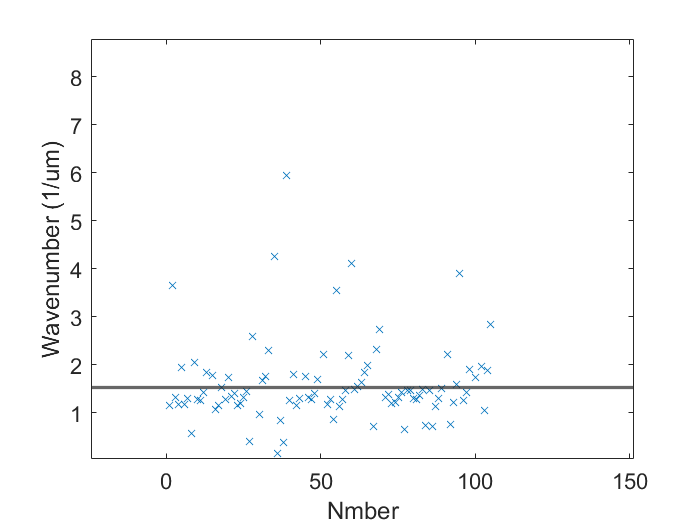

plot(1:length(qw),qw,'x');
hold on
yline(1/lambdaA,'LineWidth',2);
hold off
 ylim([-2 4]);
xlabel('Nmber') 
ylabel('Wavenumber (1/um)')
ax = gca;
ax.FontSize = 13;

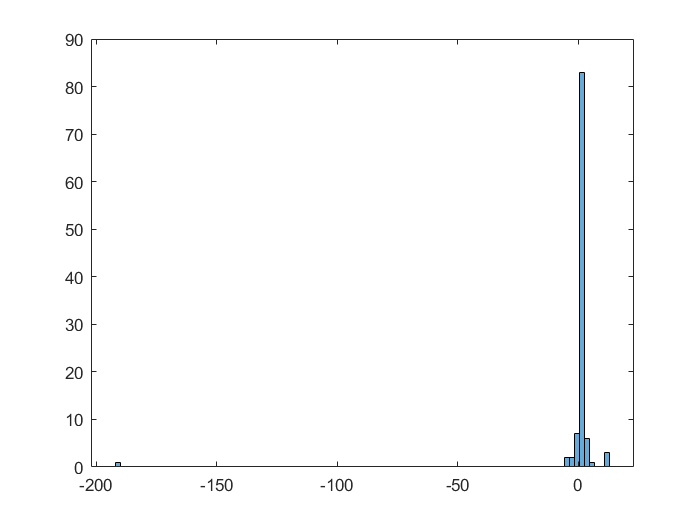

figure

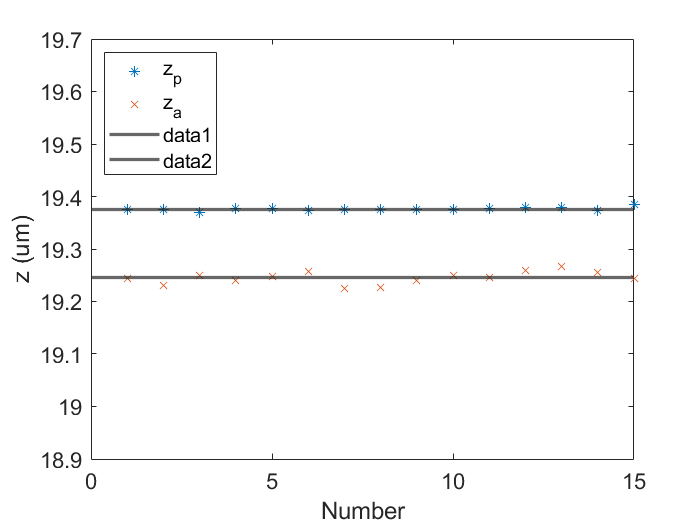

s = histogram(qw,-2:0.75:6)
edges = s.BinEdges;
counts = s.Values;
offset = diff(edges)/2;
% 在每个直方的顶部显示频次值
for i = 1:numel(counts)
    text(edges(i)+offset(i), counts(i), num2str(counts(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom')
end
% 添加标题和标签
xlabel('Wavenumber (1/um)');
ylabel('Number');
ax = gca;
ax.FontSize = 13;
%-----------------------------------------------------------------------------------



zp3 = rmoutliers(zp2,"median");
figure
plot(1:length(zp2),zp2,'*',1:Number,za2,'x');
xlabel('Number') 
ylabel('z (um)')
ax = gca;
ax.FontSize = 13;
legend('{z_p}','{z_a}','Location','northwest')
ylim([18.9 19.7]);
hold on
yline(mean(zp3),'LineWidth',2);
yline(mean(za2),'LineWidth',2);
hold off

std(za2)

ans =    0.011771557605193


std(zp3)

ans =    0.002619149438520


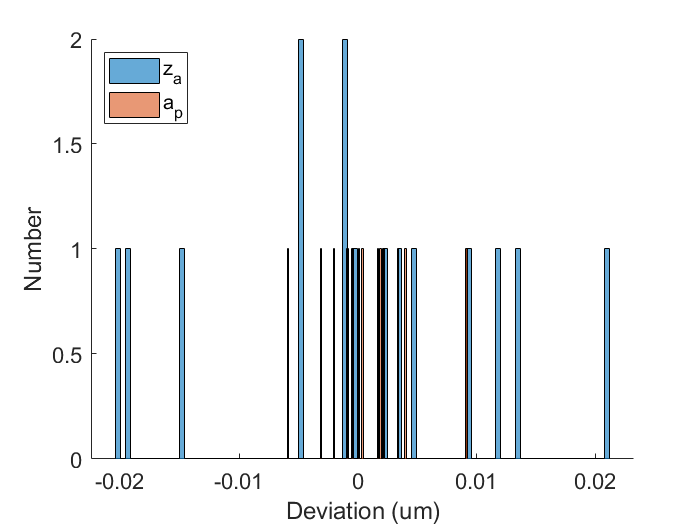


figure
% 画第一个直方图
hold on;
histogram((za2-mean(za2)),100);

% 画第二个直方图
histogram((zp2-mean(zp3)),150);

% 添加标题和标签
xlabel('Deviation (um)');
ylabel('Number');

% 添加图例
legend('{z_a}', '{a_p}','Location','northwest');
ax = gca;
ax.FontSize = 13;

% plot(zData,intensity,'LineWidth',2);
% xlabel('z (um)') 
% ylabel('Intentity (a.u.)')
% ax = gca;
% ax.FontSize = 13;
% xlim([zData(index3)-2 zData(index3)+2]);
% plot(zData,phase,'LineWidth',2);
% xlabel('z (um)') 
% ylabel('Phase (rad)');
% xlim([zData(index3)-2 zData(index3)+2]);
% ax = gca;
% ax.FontSize = 13;
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
% zadiff = za1-za
% zpdiff = zp1-zp
% z01 = za1+(a1/(4*pi));
% z02 = zp1+((a1+a0*lambdaA)/(4*pi));
% diff1 = z01-z0;
% diff2 = z02-z0;
figure;
s = 0:0.0001:2
y1 = 1.350019500809516e+02*s-2.234430832643526;
y2 = 1.353370808544154e+02*s-2.745334732022675;
k = find(abs(y1-y2)<=10^-5);
x1 = s(k);
y1k = y1(k);
hold on
plot(s,y1,s,y2,x1,y1k,'x');



function [y,n] = sigmult(x1,n1,x2,n2)
%implements y(n) = x1(n) * x2(n);
%-----------------------------------
%[y,n]=siggadd(x1,n1,x2,n2)
%x1=first sequence over n1
%x2=first sequence over n1
n = min(min(n1),min(n2)):max(max(n1),max(n2));
y1 = zeros(1,length(n));
y2 = y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1.*y2;
end

function noise = gnoise(mean1,std1,N)
MU=mean1;
SIGMA=std1;
noise(1:N)=0;
corn=15;%%%180
han=hanning(corn);%Extension=60;
han=han';
NOISE1=normrnd(MU,SIGMA,1,N+corn);%NOISE2=normrnd(MU,SIGMA,1,N+Extension);
for no=1:N
ii=no;
noise(ii)=sum(han.*NOISE1(ii:ii+corn-1))/corn;%%%%100/24差不多4um不懂含义。。。。
end
noise1 = noise(1:N);
noise1_mean = mean(noise1);
noise1_std = std(noise1);
noise = (noise1-noise1_mean)./noise1_std*SIGMA;
% noise_mean = mean(noise);
% noise_std = std(noise);
end

function [x,y]=linecross(k1,b1,k2,b2)
  if k1==k2&b1==b2
      disp('chong he');
  elseif k1==k2&b1~=b2
      disp('wu jiao dian');
  else
     x=(b2-b1)/(k1-k2);
     y=k1*x+b1;

  end
end